# **Задание 3_4**

## **Требуется:**

Построить график  функции *f*(*x*) на заданном промежутке [a; b], чтобы убедиться в наличии минимума. Определить значение функции и значение аргумента в точке минимума, используя возможности графического редактора.

Для точного определения координаты и значения минимума использовать функцию  ***fminbnd******, ***которая реализует численный метод золотого сечения или параболической интерполяции .  

Найти и вывести на печать координату и минимальное значение функции *f*(*x*) на [*a**; **b*]. Данные взять из таблицы 4.1.

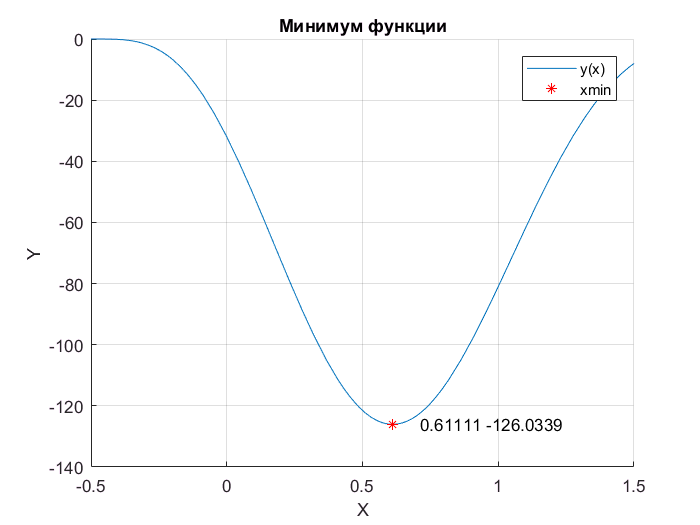

fun = @(x) (x - 2).^5 .* (2*x + 1).^4;
figure('Name', 'min', 'NumberTitle', 'off');
grid on;
hold on;
title('Минимум функции');
fplot(fun, [-0.5 1.5]);
[x, y] = fminbnd(fun, -0.5, 1.5);
plot(x, y, '*', 'Color', 'r');
xlabel('X');
ylabel('Y');
legend('y(x)', 'xmin');
a = [num2str(x), ' ', num2str(y)];
text(x + 0.1, y, a);

## **Требуется:**

Построить с помощью команды mesh (X,Y,Z) или fsurf(Z) трехмерный сетчатый график функции Z= *f*(*X**, **Y*), заданной в таблице 4.2. Для формирования сетки [X,Y] = meshgrid(…) самостоятельно задать интервал и шаг изменения элементов массивов X,Y, включая в них координаты начальной точки М0 (*х*0, *у*0). Используя возможности вращения графика и изменения масштаба изображения, убедиться в наличии минимума и выяснить его приблизительные параметры.Найти и вывести на дисплей координаты и значение минимума функции двух переменных *f*(*x**, **y*) с помощью команды  ***fminsearch***.  Получить итоговую статистику по числу итераций, количеству подсчетов оценок функции, заданным критериям для погрешностей и числовому признаку существования минимума.

Минимальное значение функции - 1, x,y = 0;

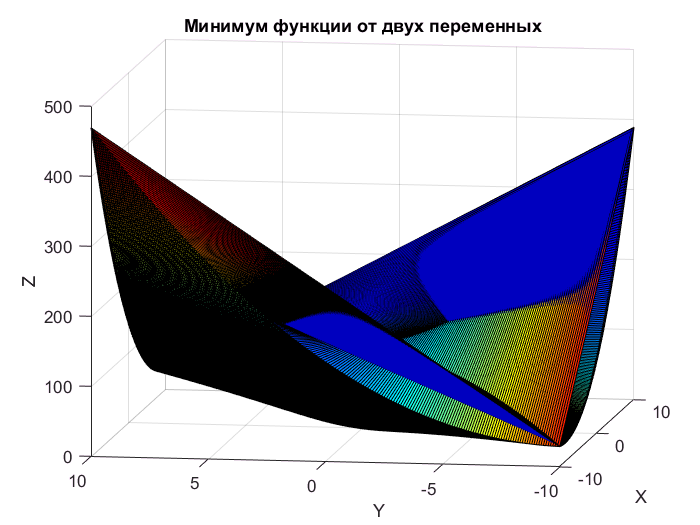

[X,Y] = meshgrid ([-10:0.1:10, -10:0.1:10]);
Z = log(1 + X.^2 + Y.^2).^2 + (X - Y - 1).^2;
figure('Name', 'fminsearch', 'NumberTitle', 'off');
surf(X, Y, Z);
view([-81 11]);
xlabel('X');
ylabel('Y');
zlabel('Z');
colormap('jet');
title('Минимум функции от двух переменных');

fun = @(x) log(1 + x(1)^2 + x(2)^2)^2 + (x(1) - x(2) - 1)^2;
[xmin, fmin] = fminsearch(fun, [2; 2]);
fmin = [fmin; fmin];
t = table;
t.X = xmin;
t.Y = fmin;
t

t = 2×2 table
       X          Y   
    ________    ______

      0.4107    0.1164
    -0.41074    0.1164
